# 034IN - Fundamentals of Automatic Control - A.Y. 2024/2025

# First Partial Examination - 2025/04/11

# Exercise 1C: Equilibrium and State Trajectory of an LTI System

**Tag List**: `[STANDARD ASSESSMENT] [PARTIAL CREDIT] [SYMBOLIC] [CONTROL TOOLBOX]`

## Introduction

Given the LTI system described by means of the following state equations


$$\left\{ \begin{array}{rcl}
\dot{x}(t) &=& \left[ \begin{array}{ccc}
2  & -5  &  0 \\
-1  &  -2 &  0 \\
0  &  0  & \alpha
\end{array} \right] \, x(t) + 
\left[ \begin{array}{c} 0 \\ 1 \\ 1 \end{array} \right] \, u(t) \\ \\
y(t)&=&\left[ \begin{array}{ccc} 1  & 0  &  1 \end{array} \right] \, x(t)
\end{array} \right. \qquad (*)$$


you are asked to 

- assume $\alpha = -1$;

- determine the **equilibrium** **state** $\bar x$, corresponding to the constant input $\bar u = +1\,, \; \forall t \ge 0$;

- calculate the state trajectory $x(t)$ for the given system, when the applied input is $\bar u$, and the initial state is $x_0 = \bar{x} + \delta_x$, where $\delta_x$ is a suitable perturbation (more details into the assignment).

## Assignment

Your code shall

### Task 1

- define the symbolic parameter `p_alpha` and assign to it the symbolic value $-1$ (pretest);

- assign the symbolic matrix `symA` with the just assigned symbolic parameter `p_alpha` (pretest);

- convert the symbolic matrix `symA` into the numeric matrix `matA`; moreover, assign the numeric matrices `matB`, `matC` and `matD` according to the state equations described in Eq, $(*)$;

### Task 2

- assign the constant input `barU`, as a numeric variable;

- determine the **equilibrium** **state** $\bar x$ and assign the solution to the numeric variable `barX`;

### Task 3

- use the preloaded variable `deltaX` to create a new initial state $x_0$ as 

- determine the **state trajectory** of the system, using `x0` as initial state and applying the constant input `barU`;

- compute the state trajectory for each time instant in the preloaded array `timeT` and assign the result to the numeric variable `varX`.

## Solution

clear
load perturbX_C.mat
load timeT_C.mat

whos deltaX timeT

  Name        Size                Bytes  Class     Attributes

  deltaX      3x1                    24  double              
  timeT       1x20001            160008  double              



### Task 1


p_alpha = sym(-1);

symA = [2,  -5,  0;
        -1,  -2,  0;
        0,   0,  p_alpha]

$$symA = \left(\begin{array}{ccc} 2 & -5 & 0\\ -1 & -2 & 0\\ 0 & 0 & -1 \end{array}\right)$$


matA = double(symA)

matA =      2    -5     0
    -1    -2     0
     0     0    -1



matB = [ 0; 
         1;
         1]

matB =      0
     1
     1



matC = [1,  0,  1]

matC =      1     0     1



matD = 0;

### Task 2

barU = +1;

% linear Eq. to solve: 
% A*barX +B*barU = 0
% barX is the unknown variable
bVect = -matB*barU;

barX = linsolve(matA, bVect)

barX =     0.5556
    0.2222
    1.0000


### Task 3

x0 = barX+deltaX;
sysLTI = ss(matA, matB, matC, matD)


sysLTI =
 
  A = 
       x1  x2  x3
   x1   2  -5   0
   x2  -1  -2   0
   x3   0   0  -1
 
  B = 
       u1
   x1   0
   x2   1
   x3   1
 
  C = 
       x1  x2  x3
   y1   1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


[yT, ~, varX] = lsim(sysLTI, barU*ones(size(timeT)), timeT, x0);


**Not requested**:

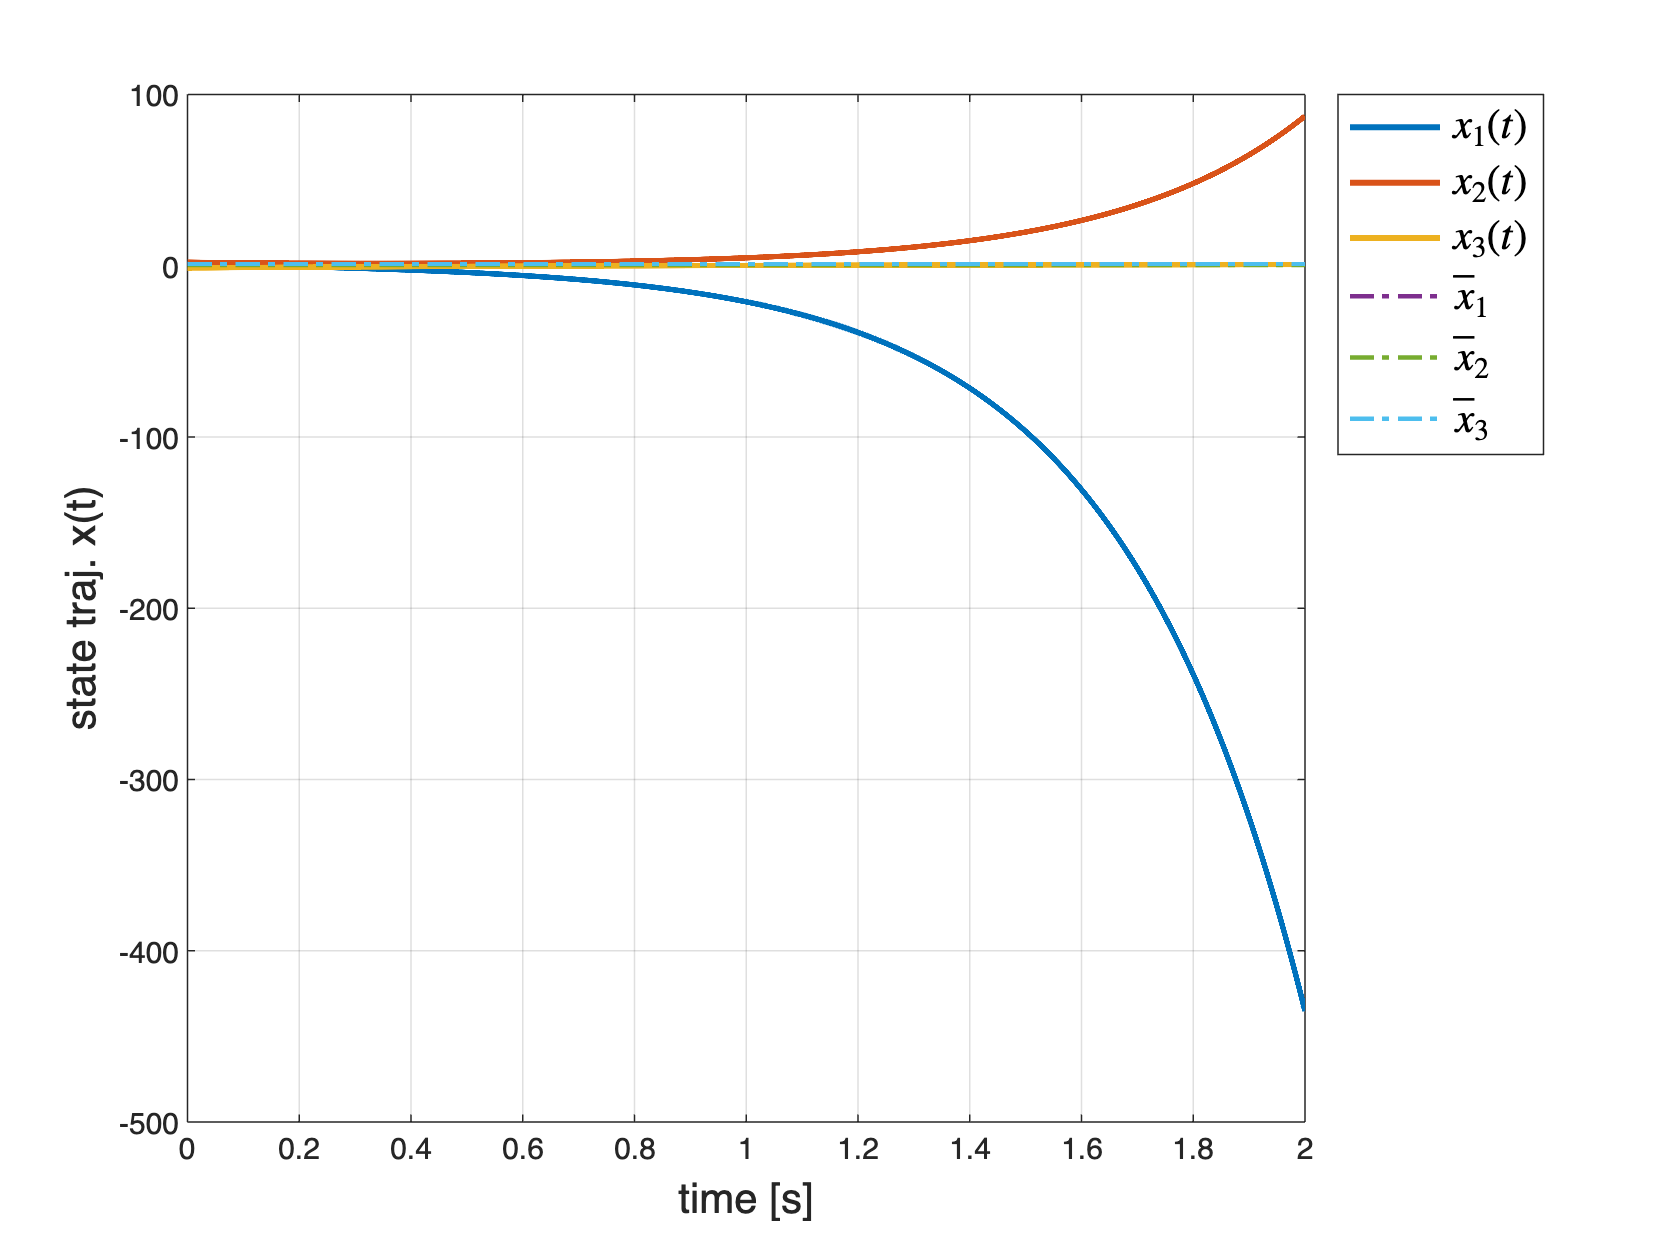

figure;
plot(timeT, varX, 'LineWidth', 2);
zoom on; grid on;
hold on
plot(timeT, barX.*ones(size(barX,1),size(timeT,2)),'LineStyle', '-.', 'LineWidth', 1.5)
xlabel('time [s]', 'fontsize', 14);
ylabel('state traj. x(t)', 'fontsize', 14);
legend('$x_1(t)$', '$x_2(t)$', '$x_3(t)$', '$\bar{x}_1$', '$\bar{x}_2$','$\bar{x}_3$',...
    'Location', 'bestoutside', 'Interpreter', 'latex', 'fontsize', 14);